# **RS-HL-3: Network Graph Generation**

UT Austin

Hongseok Kim

6/11/2024

## Scope

  Simulate a Markov Decision Process from generated dataset from RS-HL-1 Constellation Scenario Formulation

clc; clear;
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_1_Constellation_Scinario_Formulation/')

## I. Input information

### I.1 Time Parameter

% % Initial Epoch Definition

Year = 2024;
Month = 3;
Day = 21;
Hour = 0;
Minute = 0;
Seconds = 0;

% Duration and Steptime
duration = hours(24);
steptime = 15; % seconds

startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);

time_parameters.startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);
time_parameters.duration = duration;
time_parameters.steptime = steptime;

scenario = scenario_initalization(time_parameters);



### I.2 Satellite Constellation - Walker Configuration (24 SATs in Single Orbit)

% Intial Orbit Settings

Altitude = 500; % (km)
Eccentricity = 1e-5;
Inclinaton = 97.4022; % (deg)
RAAN = 90;  % (deg)
AOP = 0; % (deg)

% Number of satellites
number_of_SATs = 24;

% Satellite Characteristics - This will entail -1, -2, ... for
% constallation
satellite_name = "RS-1";

% Orbit Propagator
Orbit_Propagator = 'SGP4';


orbit_information.SMA = Altitude*1000 + 6378000;
orbit_information.ecc = Eccentricity;
orbit_information.inc = Inclinaton;
orbit_information.RAAN = RAAN;
orbit_information.AOP = AOP;

% Generate First Stream of Satellites
satellites_orbit_1 = single_orbit_constellation(scenario, orbit_information, number_of_SATs, Orbit_Propagator, satellite_name);


% Generate Second Steram of Satellites
RAAN = 105;
orbit_information.RAAN = RAAN;
satellite_name = "RS-2";
satellites_orbit_2 = single_orbit_constellation(scenario, orbit_information, number_of_SATs, Orbit_Propagator, satellite_name);

% Merge Satellite Informations
satellites = [satellites_orbit_1, satellites_orbit_2];


### I.4 gs Station Location

gs_info = ["Austin", 30.2672, -97.7431, 15;
           "New York", 40.7128, -74.0060, 10;
           "Los Angeles", 34.0522, -118.4837, 71;
           "Chicago", 41.8781, -87.6298, 181;
           "Houston", 29.7604, -95.3698, 30;
           "Phoenix", 33.4484, -112.0740, 331;
           "Philadelphia", 39.9526, -75.1652, 12;
           "San Antonio", 29.4481, -98.4936, 198;
           "San Diego", 32.7157, -117.1611, 22;
           "Dallas", 32.7767, -96.7970, 137;
           "London", 51.5074, -0.1278, 35;
           "Tokyo", 35.6895, 139.6917, 6;
           "Paris", 48.8566, 2.3522, 35;
           "Moscow", 55.7558, 37.6176, 155;
           "Sydney", -33.8688, 151.2093, 19;
           "Toronto", 43.6511, -79.3830, 76;
           "Berlin", 52.5200, 13.4050, 34;
           "Rome", 41.9028, 12.4964, 17;
           "Seoul", 37.5665, 126.9780, 23;
           "Mumbai", 19.0760, 72.8777, 14;
           "Beijing", 39.9042, 116.4074, 43;
           "Mexico City", 19.4326, -99.1332, 2240;
           "São Paulo", -23.5505, -46.6333, 780;
           "Bangkok", 13.7563, 100.5018, 2;
           "Istanbul", 41.0082, 28.9784, 39;
           "Cairo", 30.0444, 31.2357, 23;
           "Dubai", 25.2769, 55.2963, 4;
           "Singapore", 1.3521, 103.8198, 15;
           "Hong Kong", 22.3193, 114.1694, 39;
           "Sydney", -33.8688, 151.2093, 19];



gs = groundStation(scenario,"Name",gs_info(:,1), ...
                        "Latitude",str2double(gs_info(:,2)), ...
                        "Longitude", str2double(gs_info(:,3)), ...
                        "Altitude", str2double(gs_info(:,4)), ...
                        "MinElevationAngle", 15);


## II. Creat 3D ground-to-satellite contact matrix for each time step

number_of_gs =length(gs);
number_of_SATs = length(satellites);
time_vector = scenario.StartTime:seconds(scenario.SampleTime):scenario.StopTime;

gs_to_sat_contact_3d_matrix = zeros(number_of_gs, number_of_SATs, length(time_vector));

for i = 1:number_of_gs
    gs_to_sat_access_satatus = accessStatus(access(gs(i), satellites));
    gs_to_sat_contact_3d_matrix(i,:,:) = gs_to_sat_access_satatus;
end

## III. Create 3D inter-satellite contact (Diff orbit) matrix for each time step

sat1_to_sat2_contact_3d_matrix = zeros(24,24,length(time_vector));
sat2_to_sat1_contact_3d_matrix = zeros(24,24,length(time_vector));

for i = 1:24
    sat1_to_sat2_access_status = accessStatus(access(satellites_orbit_1(i),satellites_orbit_2));
    sat1_to_sat2_contact_3d_matrix(i,:,:) = sat1_to_sat2_access_status;
    sat2_to_sat1_contact_3d_matrix(:,i,:)  = sat1_to_sat2_access_status;

end


## IV.Create 3D inter-satellite contact (Same orbit) matrix for each time step

sat1_to_sat1_contact_3d_matrix = zeros(24,24,length(time_vector));

     sat1_to_sat1_contact_3d_matrix(1,1,:) = 1;
     sat1_to_sat1_contact_3d_matrix(2,1,:) = 1;
     sat1_to_sat1_contact_3d_matrix(1,2,:) = 1;
     sat1_to_sat1_contact_3d_matrix(24,1,:) = 1;
     sat1_to_sat1_contact_3d_matrix(1,24,:) = 1;

     sat1_to_sat1_contact_3d_matrix(24,24,:) = 1;
     sat1_to_sat1_contact_3d_matrix(24,23,:) = 1;
     sat1_to_sat1_contact_3d_matrix(23,24,:) = 1;
     sat1_to_sat1_contact_3d_matrix(24,1,:) = 1;
     sat1_to_sat1_contact_3d_matrix(1,24,:) = 1;



for i = 2:23
   sat1_to_sat1_contact_3d_matrix(i,i,:) = 1;
   sat1_to_sat1_contact_3d_matrix(i+1,i,:) = 1;
   sat1_to_sat1_contact_3d_matrix(i,i+1,:) = 1;
   sat1_to_sat1_contact_3d_matrix(i,i-1,:) = 1;
   sat1_to_sat1_contact_3d_matrix(i-1,i,:) = 1;
end



sat2_to_sat2_contact_3d_matrix = sat1_to_sat1_contact_3d_matrix;
sat_to_sat_contact_3d_matrix = [sat1_to_sat1_contact_3d_matrix, sat2_to_sat1_contact_3d_matrix;
                                sat1_to_sat2_contact_3d_matrix, sat2_to_sat2_contact_3d_matrix];


## V. Plot Graph and Nodes

numGroundStations = 30;
numSatellites = 48;

time_index  = 1500;

GS_to_Sat = gs_to_sat_contact_3d_matrix(:,:,time_index);
Sat_to_Sat = sat_to_sat_contact_3d_matrix(:,:,time_index);

% Create a graph object
G = graph();

% Add Ground Stations as nodes
for i = 1:numGroundStations
    G = addnode(G, sprintf('GS%d', i));
end

% Add Satellites as nodes
for i = 1:numSatellites
    G = addnode(G, sprintf('SAT%d', i));
end

% Add edges between Ground Stations and Satellites
for i = 1:numGroundStations
    for j = 1:numSatellites
        if GS_to_Sat(i, j) == 1
            G = addedge(G, sprintf('GS%d', i), sprintf('SAT%d', j));
        end
    end
end

% Add edges between Satellites
for i = 1:numSatellites
    for j = 1:numSatellites
        if Sat_to_Sat(i, j) == 1
            G = addedge(G, sprintf('SAT%d', i), sprintf('SAT%d', j));
        end
    end
end

% Plot Graph and Nodes
numGroundStations = 30;
numSatellites = 48;

time_index  = 1500;

GS_to_Sat = gs_to_sat_contact_3d_matrix(:,:,time_index);
Sat_to_Sat = sat_to_sat_contact_3d_matrix(:,:,time_index);


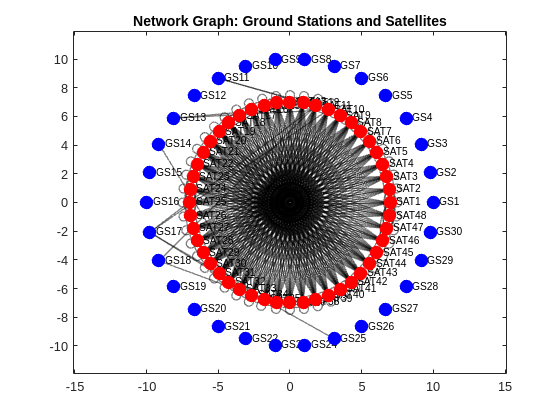

% Number of ground stations and satellites
num_ground_stations = 30;
num_satellites = 48;

% Create the node positions
ground_station_radius = 10; % Radius of the small circle for ground stations
satellite_radius = 7; % Radius of the outer circle for satellites

% Ground station positions
ground_station_angles = linspace(0, 2* pi, num_ground_stations+1);
ground_station_angles = ground_station_angles(1:end-1);
ground_station_x = ground_station_radius * cos(ground_station_angles);
ground_station_y = ground_station_radius * sin(ground_station_angles);

% Satellite positions
satellite_angles = linspace(0, 2*pi, num_satellites+1);
satellite_angles = satellite_angles(1:end-1);
satellite_x = satellite_radius * cos(satellite_angles);
satellite_y = satellite_radius * sin(satellite_angles);

% Combine the node positions
x = [ground_station_x, satellite_x];
y = [ground_station_y, satellite_y];

% Plot the network graph
figure;
plot(G, 'XData', x, 'YData', y, 'NodeColor', [0.6 0.6 0.6], 'EdgeColor', 'k', 'LineWidth', 1);
hold on;

% Plot the ground stations in blue and the satellites in red
plot(ground_station_x, ground_station_y, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
plot(satellite_x, satellite_y, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Adjust the axis limits to fit the plot
axis equal;
title('Network Graph: Ground Stations and Satellites');